# FEAGAN

**A Matlab implementation of Pix2Pix cGAN for the purposes of attempting to**

**emulate Finite Element Analysis using Machine Learning Techniques.**

Used in partial fulfilment of Masters Thesis by Stephen Douglas Trent

Methodology outline based on TensorFlow implementation at:

[www.tensorflow.org/tutorials/generative/pix2pix](www.tensorflow.org/tutorials/generative/pix2pix)

The Pix2Pix architecture originates from the paper and works of Phillip Isola et el (2016)

The original paper can be viewed [here](https://arxiv.org/abs/1611.07004).

**This Live Editor file will step through the process of:**

- Importing a paired image dataset

- Creation of the Neural Networks - Both Generator and Discriminator

- Run the Training loop for the neural networks:

- Validate trained model predictions against the Validation portion of the Datasets.

Furthermore, the models and majority of functions utilized here are implemented into a standalone GUI 

for the purposes of generating predictions for user inputs.

## Custom MATLAB functions

The following custom files need to be present in the working directory in order to execute this Live Editor

datapath.mlx                -   Specify file (dataset) locations 

discriminator_loss        -    Caluclates Discriminator losses

extract_img.mlx            -    Extracts combined image from a dataset

ganLoss                       -    Calculates the losses associated with the Generator

generator_loss             -    Generator loss function

load_checkpoint           -    Load a random/specific/latest saved model checkpoint

load_img.mlx                -    Converts combined indexed '.png' or uint8 files to RGBimage files and splits into two images

load_image_test.mlx    -    Calls required sequence of image preprocessing functions for testing

load_image_train.mlx   -    Calls required sequence of image preprocessing functions for training

modelGradients.mlx     -    Internal prediction->discriminate->gradients generation for network learning

normalize_img.mlx       -    Normalizes image depth (channels) between [-1,1] for input into neural net

random_crop.mlx         -    Randomly crop out a smaller image from a larger one

random_jitter.mlx          -    Upsizes and randomly crops images to avoid overfitting (calls both above functions)

resize_img.mlx             -    scales input image to specified dimensions eg. 256x256 pixels

In order to run the training loop the **Machine Learning Toolbox** addin is required.

Furthermore, whilst not essential, a CUDA capable GPU is recommended for quicker training.

## Matlab Housekeeping:

clear                       %Clear matlab workspace
gpudev = gpuDevice([]);      %Use hardware GPU (Must be Nvidia CUDA capable)

Error using gpuDevice (line 26)
Unable to load CUDA driver. The library name used was nvcuda.dll. The error was:
The specified module could not be found.

Update or reinstall your GPU driver. For more information on GPU support, see GPU Support by Release.

reset(gpudev);              %Clear gpu memory
clc;                        %Clear command window

## Select Training Dataset

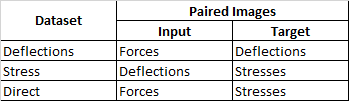

Dataset ='Deflections'

Dataset = 'Deflections'

#### **Define the Input Parameters to the Neural Network:**

IMG_WIDTH = 256 ;           %Image input size into NN in Pixels - larger or smaller images will be scaled to these values
IMG_HEIGHT = 256;
IMG_DEPTH = 3;              %channel depth -for RGB=3

## **Input Pipeline**

**Define the datastores and the function sequences which process the data as it's read from the datastores**

% Get data folder path
directoryPath = uigetdir('C:\', 'Select the path of data files');
fullPath = [directoryPath '\' 'combined*'];
% create data store for data
allImages = imageDatastore(fullPath,'LabelSource', 'foldernames','ReadFcn',@extract_img);

% Split data for training the netwrok
[train_dataset,test_dataset,val_dataset] = splitEachLabel(allImages,0.66667,0.16667,'randomized');
% Shuffle data for training, testing and validation
train_dataset=shuffle(train_dataset); %shuffle only available in matlab R2020a onwards
test_dataset=shuffle(test_dataset);
val_dataset=shuffle(val_dataset);

## Results Folder

% Create folder to save all results and workspace
resultsPath = [directoryPath '\' Dataset '\Results'];
[status, msg, msgID] = mkdir(resultsPath)

status = logical
   1



msg =

  0×0 empty char array


msgID =

  0×0 empty char array



## Test Functions:

Test the custom functions which serve to process the data

### Test "load_img.mlx"

- reads in a combined image 

- splits the image into two images

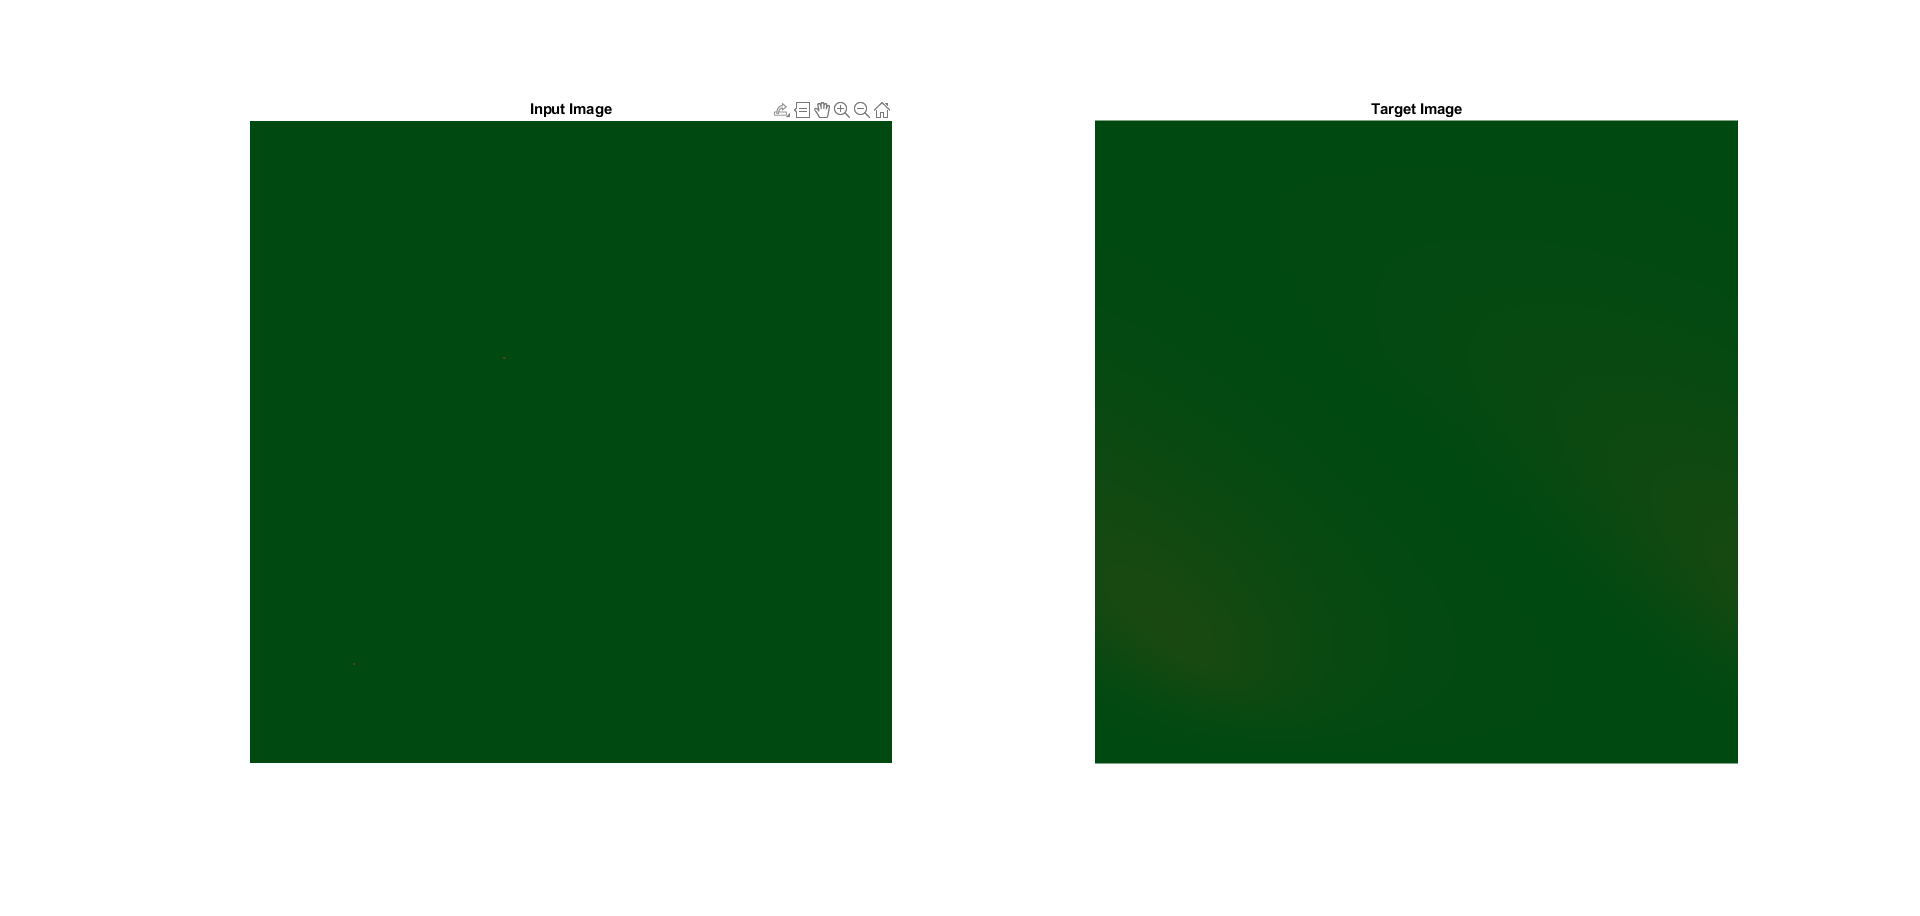

% Create random to choose random sample from training data
r = randi([0,length(train_dataset.Files)],1,1);
directorypath=train_dataset.Files(r);
% read image file
[inp,re]=load_img(char(directorypath),'png',1,2);

fig=figure();
subplot(1,2,1);
imshow(inp);
title('Input Image')

subplot(1,2,2);
imshow(re);
title('Target Image')
set(fig,'WindowStyle','docked') % Insert the figure to dock
figureName = 'Random Sample Image.fig';
savefig(fig,[ resultsPath '\' figureName])

### Test of "random_jitter.mlx" function

- Upsizes beyond image specifications

- Randomly crops out original sized image

- Randomly mirrors about x and y axes

- The above serves to add additional variation to the training images in order to avoid overfitting

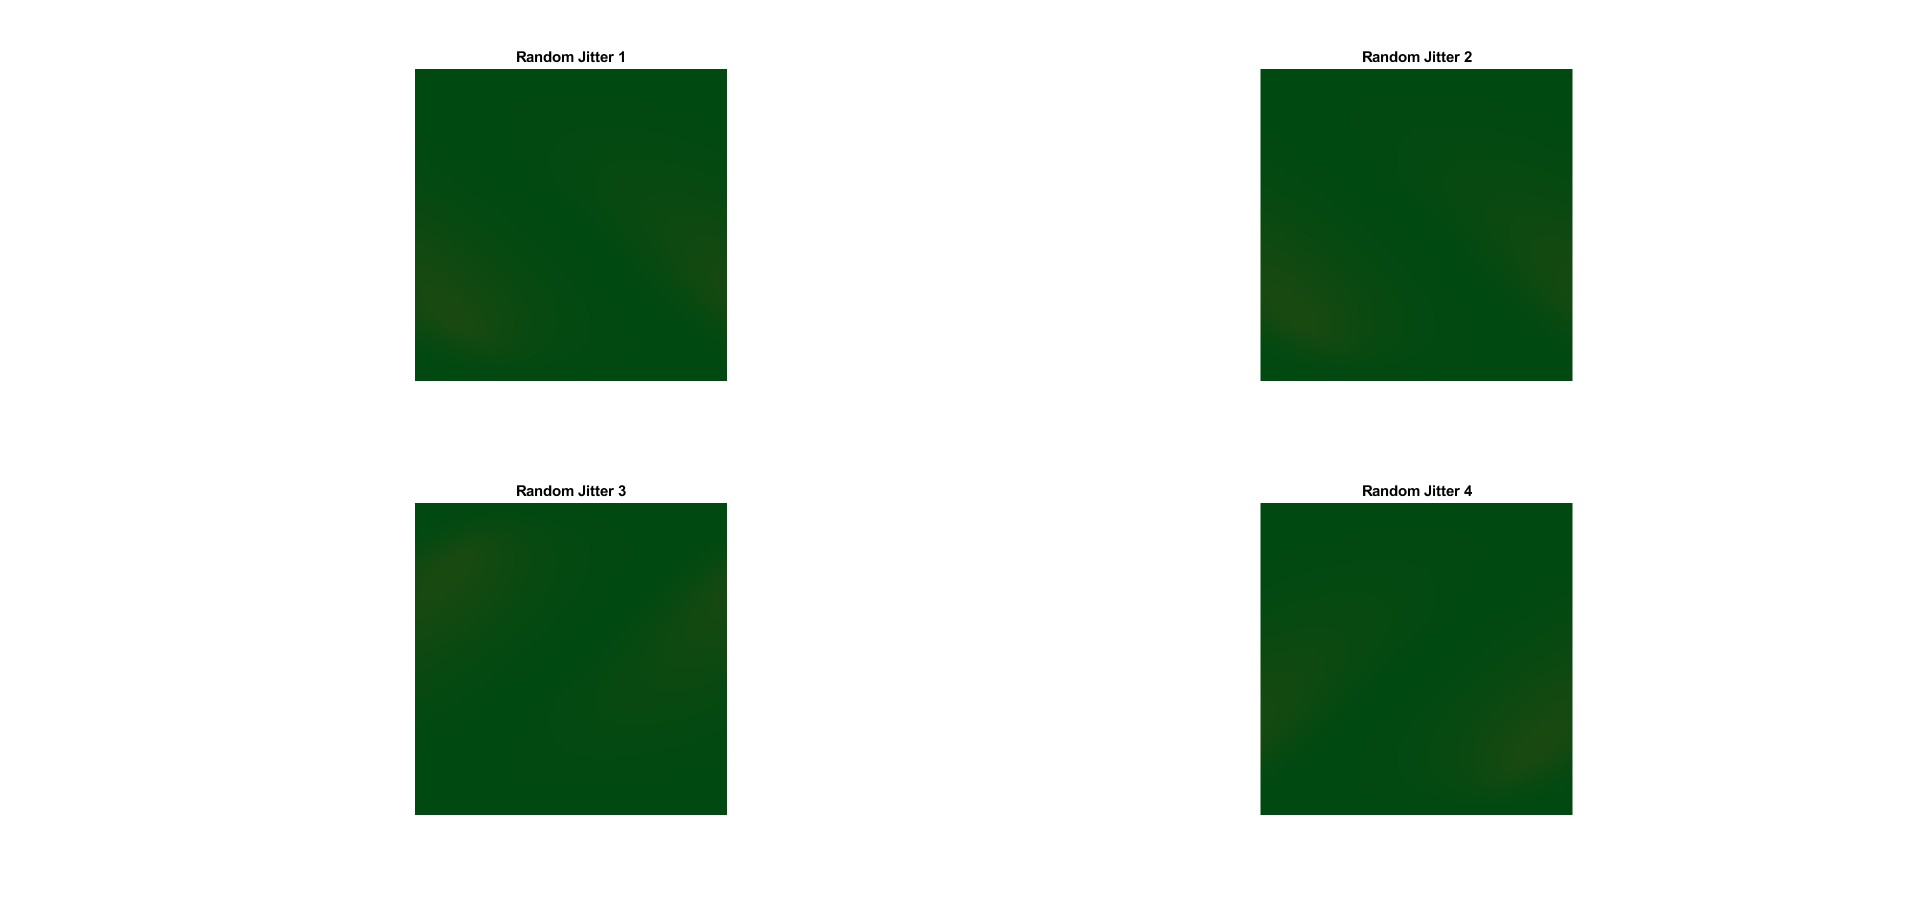

fig=figure("Name",'Randomly jittered sections of image');
for i=1:4
    [rj_inp,rj_re]=random_jitter(inp,re);
    subplot(2,2,i);
    imshow(rj_re)
    title(['Random Jitter ' num2str(i)])
end
set(fig,'WindowStyle','docked') % Insert the figure to dock
figureName = 'Randomly jittered sections of image.fig';
savefig(fig,[ resultsPath '\' figureName])

# **Create Deep Learning Network Architecture**

Scripts for creating the layers for Pix2Pix deep learning network Generator:

## Create the Generator Network

The Generator is structured as an auto encoder-decoder network with forward bridge connections which results in a "U-net" structure.

The** Encoder segment** is comprised of successive groupings of :

**2D convolution->BatchNormalization->Leaky ReLU Layers** 

whilst the **Decoder segment** is comprised of successive groupings of: 

**Depth Concatenation -> transposed 2D Convolution-> batchNormalization->leaky RELu**

There are also additional** dropout layers** to avoid overfitting during training.

Create the layer graph variable to contain the network's layers:

lgraph = layerGraph();

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = imageInputLayer([256 256 3],"Name","inputImage","Normalization","none");
lgraph = addLayers(lgraph,tempLayers);%

tempLayers = [
    convolution2dLayer([4 4],64,"Name","conv2d_1","BiasLearnRateFactor",0,"Padding","same","Stride",[2 2])
    leakyReluLayer(0.3,"Name","leaky_re_lu_1")];%
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([4 4],128,"Name","conv2d_2","BiasLearnRateFactor",0,"Padding","same","Stride",[2 2])
    batchNormalizationLayer("Name","batch_normalization_2","Epsilon",0.001)
    leakyReluLayer(0.3,"Name","leaky_re_lu_2")];%
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([4 4],256,"Name","conv2d_3","BiasLearnRateFactor",0,"Padding","same","Stride",[2 2])
    batchNormalizationLayer("Name","batch_normalization_3","Epsilon",0.001)
    leakyReluLayer(0.3,"Name","leaky_re_lu_3")];%
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([4 4],512,"Name","conv2d_4","BiasLearnRateFactor",0,"Padding","same","Stride",[2 2])
    batchNormalizationLayer("Name","batch_normalization_4","Epsilon",0.001)
    leakyReluLayer(0.3,"Name","leaky_re_lu_4")];%
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([4 4],512,"Name","conv2d_5","BiasLearnRateFactor",0,"Padding","same","Stride",[2 2])
    batchNormalizationLayer("Name","batch_normalization_5","Epsilon",0.001)
    leakyReluLayer(0.3,"Name","leaky_re_lu_5")];%
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([4 4],512,"Name","conv2d_6","BiasLearnRateFactor",0,"Padding","same","Stride",[2 2])
    batchNormalizationLayer("Name","batch_normalization_6","Epsilon",0.001)
    leakyReluLayer(0.3,"Name","leaky_re_lu_6")];%
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([4 4],512,"Name","conv2d_7","BiasLearnRateFactor",0,"Padding","same","Stride",[2 2])
    batchNormalizationLayer("Name","batch_normalization_7","Epsilon",0.001)
    leakyReluLayer(0.3,"Name","leaky_re_lu_7")];%
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([4 4],512,"Name","conv2d_8","BiasLearnRateFactor",0,"Padding","same","Stride",[2 2])
    batchNormalizationLayer("Name","batch_normalization_8","Epsilon",0.001)
    leakyReluLayer(0.3,"Name","leaky_re_lu_8")
    transposedConv2dLayer([4 4],512,"Name","conv2d_transpose_1","BiasLearnRateFactor",0,"Cropping","same","Stride",[2 2])
    batchNormalizationLayer("Name","batch_normalization_9","Epsilon",0.001)
    dropoutLayer(0.5,"Name","dropout")
    reluLayer("Name","re_lu_1")];%
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","concatenate")
    transposedConv2dLayer([4 4],512,"Name","conv2d_transpose_2","BiasLearnRateFactor",0,"Cropping","same","Stride",[2 2])
    batchNormalizationLayer("Name","batch_normalization_10","Epsilon",0.001)
    dropoutLayer(0.5,"Name","dropout_1")
    reluLayer("Name","re_lu_2")];%
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","concatenate_1")
    transposedConv2dLayer([4 4],512,"Name","conv2d_transpose_3","BiasLearnRateFactor",0,"Cropping","same","Stride",[2 2])
    batchNormalizationLayer("Name","batch_normalization_11","Epsilon",0.001)
    dropoutLayer(0.5,"Name","dropout_2")
    reluLayer("Name","re_lu_3")];%
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","concatenate_2")
    transposedConv2dLayer([4 4],512,"Name","conv2d_transpose_4","BiasLearnRateFactor",0,"Cropping","same","Stride",[2 2])
    batchNormalizationLayer("Name","batch_normalization_12","Epsilon",0.001)
    reluLayer("Name","re_lu_4")];%
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","concatenate_3")
    transposedConv2dLayer([4 4],256,"Name","conv2d_transpose_5","BiasLearnRateFactor",0,"Cropping","same","Stride",[2 2])
    batchNormalizationLayer("Name","batch_normalization_13","Epsilon",0.001)
    reluLayer("Name","re_lu_5")];%
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","concatenate_4")
    transposedConv2dLayer([4 4],128,"Name","conv2d_transpose_6","BiasLearnRateFactor",0,"Cropping","same","Stride",[2 2])
    batchNormalizationLayer("Name","batch_normalization_14","Epsilon",0.001)
    reluLayer("Name","re_lu_6")];%
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","concatenate_5")
    transposedConv2dLayer([4 4],64,"Name","conv2d_transpose_7","BiasLearnRateFactor",0,"Cropping","same","Stride",[2 2])
    batchNormalizationLayer("Name","batch_normalization_15","Epsilon",0.001)
    reluLayer("Name","re_lu_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","concatenate_6")
    transposedConv2dLayer([4 4],3,"Name","conv2d_transpose_8","Cropping","same","Stride",[2 2])];
%tanhLayer("Name","conv2d_transpose_8_tanh")]; %apply tanh outside
%layers
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

lgraph = connectLayers(lgraph,"inputImage","conv2d_1");
lgraph = connectLayers(lgraph,"leaky_re_lu_1","conv2d_2");
lgraph = connectLayers(lgraph,"leaky_re_lu_1","concatenate_6/in2");
lgraph = connectLayers(lgraph,"leaky_re_lu_2","conv2d_3");
lgraph = connectLayers(lgraph,"leaky_re_lu_2","concatenate_5/in2");
lgraph = connectLayers(lgraph,"leaky_re_lu_3","conv2d_4");
lgraph = connectLayers(lgraph,"leaky_re_lu_3","concatenate_4/in2");
lgraph = connectLayers(lgraph,"leaky_re_lu_4","conv2d_5");
lgraph = connectLayers(lgraph,"leaky_re_lu_4","concatenate_3/in2");
lgraph = connectLayers(lgraph,"leaky_re_lu_5","conv2d_6");
lgraph = connectLayers(lgraph,"leaky_re_lu_5","concatenate_2/in2");
lgraph = connectLayers(lgraph,"leaky_re_lu_6","conv2d_7");
lgraph = connectLayers(lgraph,"leaky_re_lu_6","concatenate_1/in2");
lgraph = connectLayers(lgraph,"leaky_re_lu_7","conv2d_8");
lgraph = connectLayers(lgraph,"leaky_re_lu_7","concatenate/in2");
lgraph = connectLayers(lgraph,"re_lu_1","concatenate/in1");
lgraph = connectLayers(lgraph,"re_lu_2","concatenate_1/in1");
lgraph = connectLayers(lgraph,"re_lu_3","concatenate_2/in1");
lgraph = connectLayers(lgraph,"re_lu_4","concatenate_3/in1");
lgraph = connectLayers(lgraph,"re_lu_5","concatenate_4/in1");
lgraph = connectLayers(lgraph,"re_lu_6","concatenate_5/in1");
lgraph = connectLayers(lgraph,"re_lu_7","concatenate_6/in1");

**Clean Up Helper Variable**

clear tempLayers;

### Convert layer graph to deep learning network object:

This allows us to train the network within the training loop

generator=dlnetwork(lgraph)

generator =   dlnetwork with properties:

         Layers: [56×1 nnet.cnn.layer.Layer]
    Connections: [62×2 table]
     Learnables: [60×3 table]
          State: [28×3 table]
     InputNames: {'inputImage'}
    OutputNames: {'conv2d_transpose_8'}


### Plot the Layers of "generator"

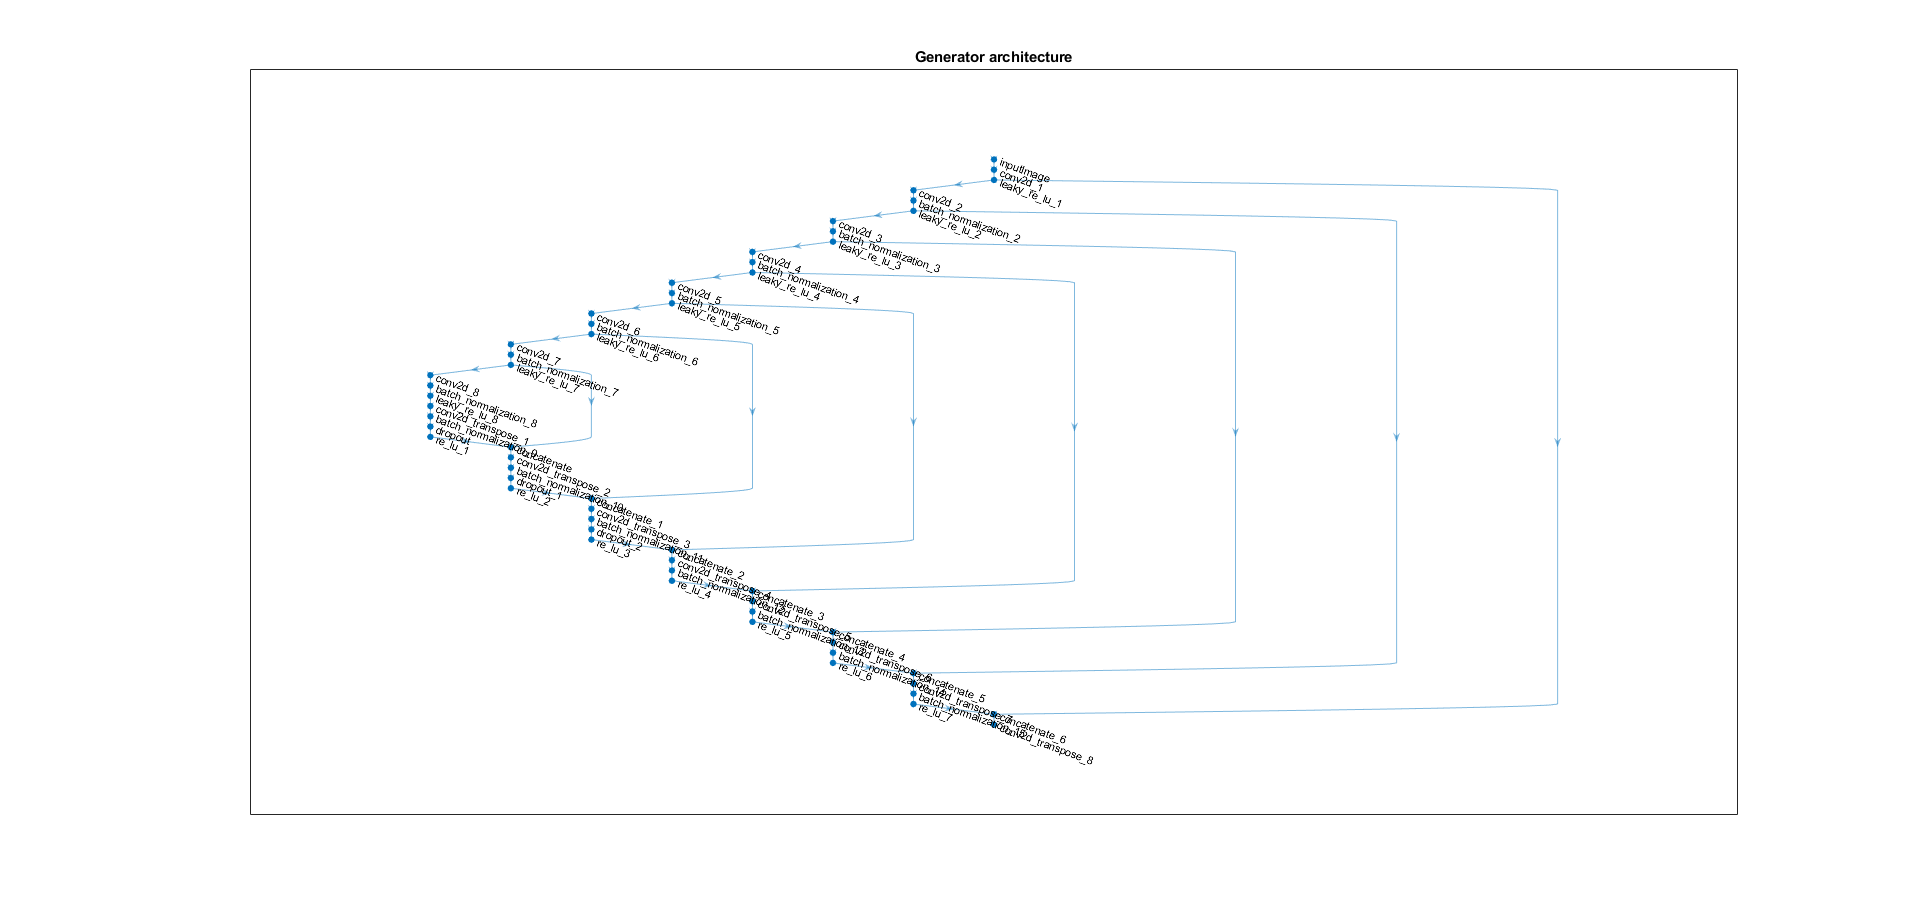

fig = figure;
plot(lgraph);
% analyzeNetwork(lgraph) % Uncomment to view Analysis
title("Generator architecture");
set(fig,'WindowStyle','docked') % Insert the figure to dock
figureName = 'Generator architecture.fig';
savefig(fig,[ resultsPath '\' figureName])

Clear Layergraph from memory

clear("lgraph");

## Generator Loss:

- a sigmoid cross entropy loss of the generated images and an **array of ones**- ones representing being absolutely "real"

- the paper (Phillip Isola et el) also includes an L1 loss which is Mean Absolute Error between the generated image and the target image.

- This allows the generated image to become structurally similar to the target image

- the formula to calculate the total generator loss:

  
$$\begin{array}{l}
\textrm{total}\;\textrm{generator}\;\textrm{loss}={\textrm{gan}}_- \textrm{loss}+\lambda \times \textrm{L1}\_\textrm{loss}\\
\textrm{where}\;\lambda =100
\end{array}$$


.

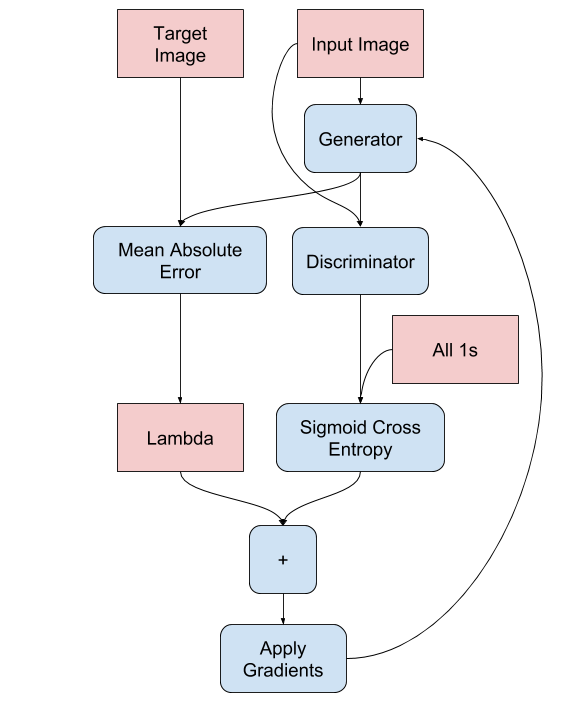

## Create Discriminator Architecture

Script for creating the layers for a deep learning Discriminator network with the following properties:

The **Discriminator** is a '**PatchGan**'  Convolutional Neural Network (CNN) classifier which compares patches of the generated images against corresponding patches of the Target image and computes a loss which serves to improve the subsequent Generated images.

### Create Layer Graph

Create the layer graph variable to contain the network layers.

lgraph = layerGraph();

## Create Array of Layers

layers = [
    imageInputLayer([256 256 6],"Name","inputImage","Normalization","none")
    convolution2dLayer([4 4],64,"Name","conv2d_9","BiasLearnRateFactor",0,"Padding","same","Stride",[2 2])
    leakyReluLayer(0.3,"Name","leaky_re_lu_9")
    convolution2dLayer([4 4],128,"Name","conv2d_10","BiasLearnRateFactor",0,"Padding","same","Stride",[2 2])
    batchNormalizationLayer("Name","batch_normalization_16","Epsilon",0.001)
    leakyReluLayer(0.3,"Name","leaky_re_lu_10")
    convolution2dLayer([4 4],256,"Name","conv2d_11","BiasLearnRateFactor",0,"Padding","same","Stride",[2 2])
    batchNormalizationLayer("Name","batch_normalization_17","Epsilon",0.001)
    leakyReluLayer(0.3,"Name","leaky_re_lu_11")
    convolution2dLayer([1 1],512,"Name","conv_zero_pad1","BiasInitializer","ones","BiasLearnRateFactor",0,"Padding",[1 1 1 1],"WeightL2Factor",0,"WeightLearnRateFactor",0,"WeightsInitializer","ones")
    convolution2dLayer([4 4],512,"Name","conv2d_12","BiasLearnRateFactor",0)
    batchNormalizationLayer("Name","batch_normalization_18","Epsilon",0.001)
    leakyReluLayer(0.3,"Name","leaky_re_lu_12")
    convolution2dLayer([1 1],31,"Name","conv_zero_pad2","BiasInitializer","ones","BiasLearnRateFactor",0,"Padding",[1 1 1 1],"WeightL2Factor",0,"WeightLearnRateFactor",0,"WeightsInitializer","ones")
    convolution2dLayer([4 4],1,"Name","OutputLayer")];

### Connect Layer Branches

Connect all the branches of the network to create the network graph.

lgraph = addLayers(lgraph,layers);

### Convert the layer graph to a deep learning network object:

This allows us to train the network with the training loop 

discriminator=dlnetwork(lgraph)

discriminator =   dlnetwork with properties:

         Layers: [15×1 nnet.cnn.layer.Layer]
    Connections: [14×2 table]
     Learnables: [20×3 table]
          State: [6×3 table]
     InputNames: {'inputImage'}
    OutputNames: {'OutputLayer'}


### Plot the layers of "discriminator"

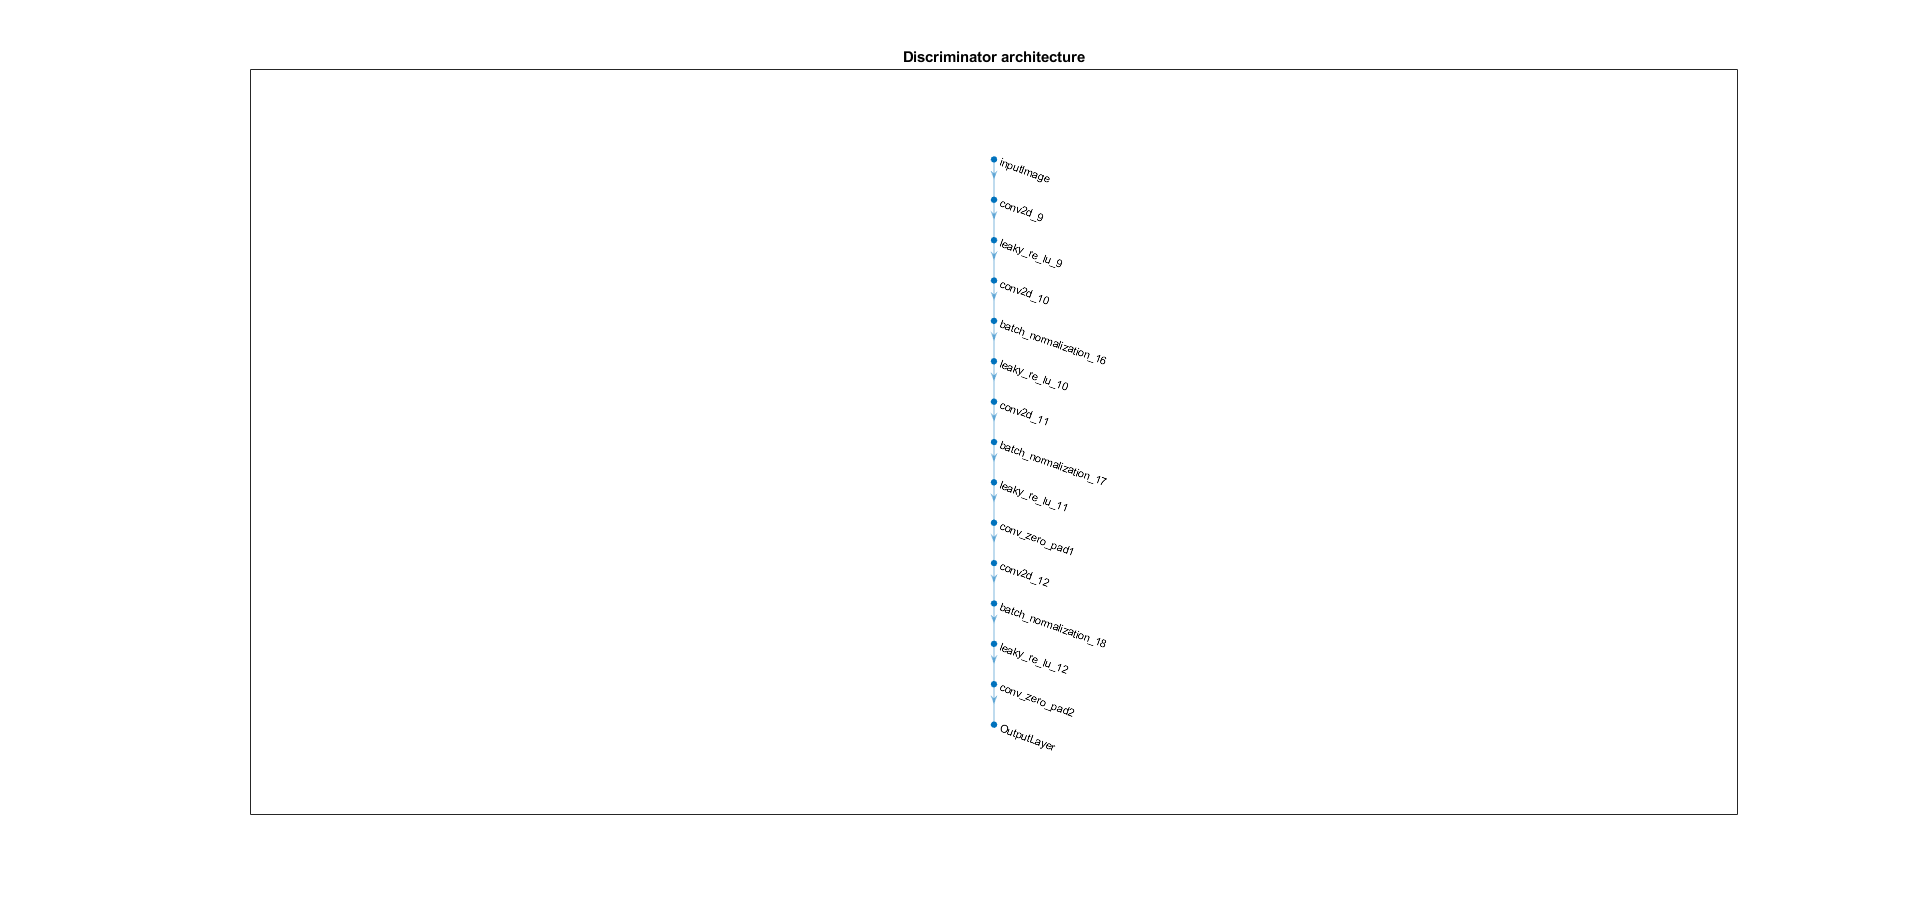

fig = figure;
plot(lgraph);
%analyzeNetwork(lgraph)
title("Discriminator architecture")
set(fig,'WindowStyle','docked') % Insert the figure to dock
figureName = 'Discriminator architecture.fig';
savefig(fig,[ resultsPath '\' figureName])

clear("lgraph")

## **Discriminator loss**

- The discriminator loss function takes 2 inputs; **real images, generated images**

- real_loss is a sigmoid cross entropy loss of the **real images** and an **array of ones (since these are the real images)**

- generated_loss is a sigmoid cross entropy loss of the **generated images** and an **array of zeros(since these are the fake images)**

- Then the total_loss is the **sum of real_loss and the generated_loss**

The training procedure for the discriminator is shown below.

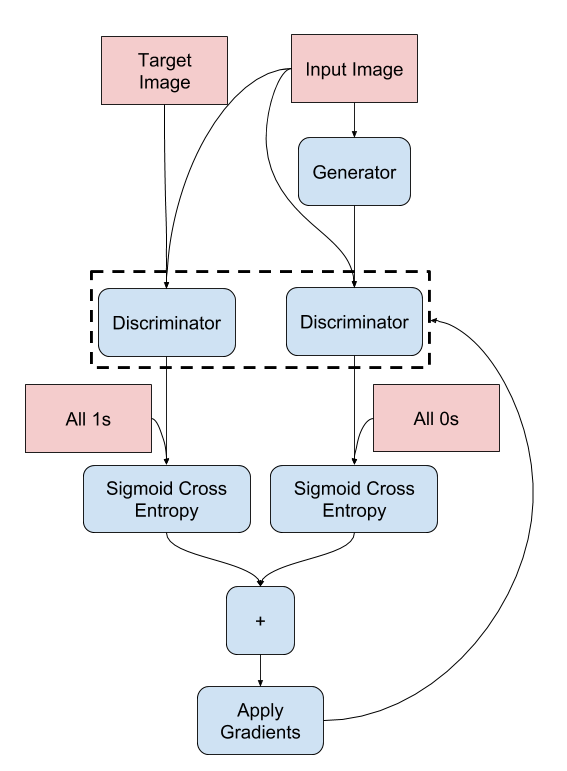

## Training Checkpoint locations

checkpoint_dir = fullfile(directoryPath,Dataset,'checkpoints');
mkdir([checkpoint_dir '\' Dataset])

## Define the Training Inputs and Network Optimizers

These alter the inputs which affect the rate at which changes are made to the Neural networks each alteration.

% Set Environmental variables
executionEnvironment = "auto"; %detemines if only CPU or GPU is available.

env         = "auto";   %Execution environment - "auto","cpu" or "gpu"
learnRate   = 2e-4;     %InitialLearnRate
beta1       = 0.5;      %GradientDecayFactor
beta2       = 0.999;    %SquaredGradientDecayFactor
MaxEpochs   = 200;      %Maximum epochs
batchSize   = 32;       %MiniBatchSize - number of images taken during each iteration

Assign to the relevant optimizers:

generator_optimizer = trainingOptions("adam",...
    "InitialLearnRate",learnRate,...
    "GradientDecayFactor",beta1,...
    "SquaredGradientDecayFactor",beta2,...
    "MaxEpochs",MaxEpochs,...
    "MiniBatchSize",batchSize,...
    "ExecutionEnvironment",env)

generator_optimizer =   TrainingOptionsADAM with properties:

           GradientDecayFactor: 0.5000
    SquaredGradientDecayFactor: 0.9990
                       Epsilon: 1.0000e-08
              InitialLearnRate: 2.0000e-04
             LearnRateSchedule: 'none'
           LearnRateDropFactor: 0.1000
           LearnRateDropPeriod: 10
              L2Regularization: 1.0000e-04
       GradientThresholdMethod: 'l2norm'
             GradientThreshold: Inf
                     MaxEpochs: 200
                 MiniBatchSize: 32
                       Verbose: 1
              VerboseFrequency: 50
                ValidationData: []
           ValidationFrequency: 50
            ValidationPatience: Inf
                       Shuffle: 'once'
                CheckpointPath: ''
          ExecutionEnvironment: 'auto'
                    WorkerLoad: []
                     OutputFcn: []
                         Pl

%,"CheckpointPath",checkpoint_dir)
discriminator_optimizer = trainingOptions("adam",...
    "InitialLearnRate",learnRate,...
    "GradientDecayFactor",beta1,...
    "SquaredGradientDecayFactor",beta2,...
    "MaxEpochs",MaxEpochs,...
    "MiniBatchSize",batchSize,...
    "ExecutionEnvironment",env)

discriminator_optimizer =   TrainingOptionsADAM with properties:

           GradientDecayFactor: 0.5000
    SquaredGradientDecayFactor: 0.9990
                       Epsilon: 1.0000e-08
              InitialLearnRate: 2.0000e-04
             LearnRateSchedule: 'none'
           LearnRateDropFactor: 0.1000
           LearnRateDropPeriod: 10
              L2Regularization: 1.0000e-04
       GradientThresholdMethod: 'l2norm'
             GradientThreshold: Inf
                     MaxEpochs: 200
                 MiniBatchSize: 32
                       Verbose: 1
              VerboseFrequency: 50
                ValidationData: []
           ValidationFrequency: 50
            ValidationPatience: Inf
                       Shuffle: 'once'
                CheckpointPath: ''
          ExecutionEnvironment: 'auto'
                    WorkerLoad: []
                     OutputFcn: []
                       

%"CheckpointPath",checkpoint_dir)

## Generate Images

- We pass images from the test dataset to the generator.

- The generator will then translate the input image into the output.

- Plot the predictions learning stats

%Example output:
[range, ~]= size(test_dataset.Files);
s=round(rand()*(range-1))+1;
image_file=extract_img(test_dataset.Files(s));
[example_input, example_target]=load_image_test(image_file);

test_input=dlarray(example_input,"SSCB");       %Size,Size,#Channels,Batch#

 For GPU training, convert the data to gpuArray objects.


if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
    test_input = gpuArray(test_input);
end

Pass the test_input to the (untrained) generator

prediction=predict(generator,test_input);

Convert back from GPU/Deep Learning array:

predictionArray=tanh(gather(extractdata(prediction)));

### Reverse normalization and convert arrays into rgb images:

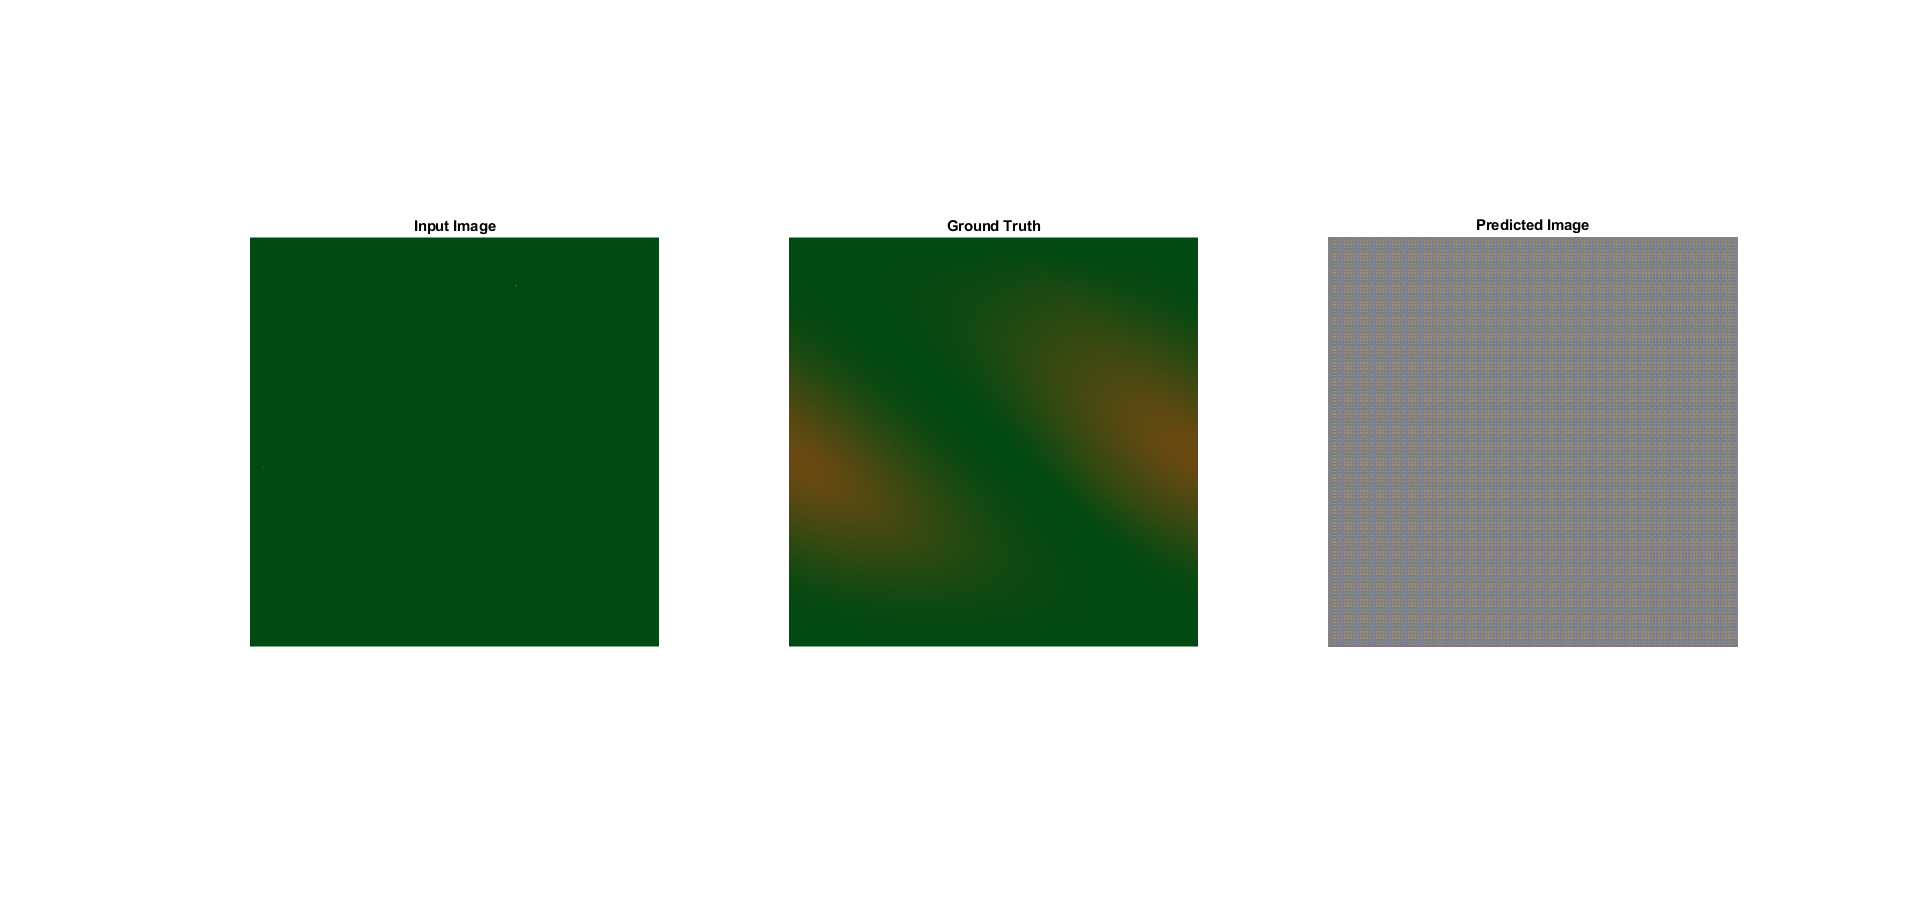

RGBexample_input=normalize_img(example_input,1,'backward');

RGBexample_target=normalize_img(example_target,1,'backward');

RGBprediction=normalize_img(predictionArray,1,'backward');


display_list={RGBexample_input;RGBexample_target;RGBprediction};
Imgtitles =["Input Image","Ground Truth","Predicted Image"];
fig=figure;
for i=1:3
    subplot(1,3,i);
    
    imshow(display_list{i},gray);
    title(Imgtitles{i});
end
set(fig,'WindowStyle','docked') % Insert the figure to dock *************************
figureName = 'Test Network befor Training.fig';
savefig(fig,[ resultsPath '\' figureName])

#### **Clear all examples and test data up to this point**

close(figure);
clear ans...
    display_list...
    example_input...
    example_target...
    fig...
    files...
    i...
    image_file...
    Imgtitles...
    inp...
    layers...
    prediction...
    predictionArray...
    re...
    RGBexample_input...
    RGBexample_target...
    RGBprediction...
    rj_inp...
    rj_re...
    range...
    s;



# Train the model

===============Training Loop===================================

**1 Read batches of paired images from the training dataset**

**2 Process the paired images:**

        *Split into seperate "input" and "target/response" images

        *apply random jitter - upscale and crop back down to required dimensions

        *randomly flip along up-down / left-right axes

        *normalise date values between [-1,1]

**3 Create prediction from "input" image parsed to Generator network**

**4 Compare "real" vs "fake" images using the Discriminator:**

        *Analyse input image against "ground truth" target image

        *Analyse input image against "prediction" image

        *Determine training losses from the above

        *Determine gradients from above losses 

**5 Apply gradients to Generator and Discriminator networks**

**        ***Makes use of ADAM 

**6 Plot Iterative results**

**        ***Generated Image vs Ground Truth Image

        **G* and *D* losses

**7 Iterate loop**

============================================================

## Set Environmental and Training variables

saveFreq = 4;                %interval between checkpoint saves (in epochs)
validationFrequency = 10;    %Frequency of output progress display during training (lower = more frequent)

%Parameters for ADAM
%These are the model "gradients" which change between iterations
trailingAvgGenerator = [];
trailingAvgSqGenerator = [];
trailingAvgDiscriminator = [];
trailingAvgSqDiscriminator = [];

## Setup Figures and Plots

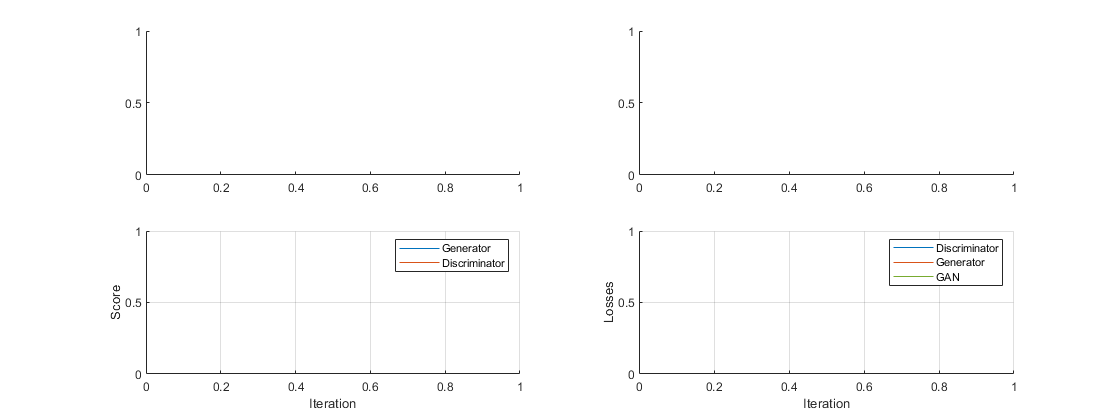

%Create Axes to display Progress:

f = figure;
f.Position(3) = 2*f.Position(3);

%Create a subplot for the generated images and the newtork scores.
targetAxes = subplot(2,2,1);

imageAxes = subplot(2,2,2);

scoreAxes = subplot(2,2,3);
lineScoreGenerator = animatedline(scoreAxes,'Color',[0 0.447 0.741]);
lineScoreDiscriminator = animatedline(scoreAxes, 'Color', [0.85 0.325 0.098]);
legend('Generator','Discriminator');
ylim([0 1]);
xlabel("Iteration");
ylabel("Score");
grid on;

lossAxes = subplot(2,2,4);
lineDLoss = animatedline(lossAxes,'Color',[0 0.447 0.741]);
lineGLoss = animatedline(lossAxes, 'Color', [0.85 0.325 0.098]);
lineGanLoss = animatedline(lossAxes, 'Color', [0.47 0.67 0.19]);
legend('Discriminator','Generator','GAN');
xlabel("Iteration");
ylabel("Losses");
grid on;

## Initialize counters

Epoch=0;
iteration = 0;

### **Load Checkpoint if it exists**

See ***Load_checkpoint.mlx***

checklistName = '\checklist.mat';
checklistFile=fullfile(checkpoint_dir, Dataset, checklistName);
index=0;
if isfile(checklistFile)
    [generator_optimizer,...
        discriminator_optimizer,...
        generator,...
        discriminator,...
        Epoch,...
        iteration,...
        trailingAvgGenerator,...
        trailingAvgSqGenerator,...
        trailingAvgDiscriminator,...
        trailingAvgSqDiscriminator]=load_checkpoint(checkpoint_dir, Dataset, checklistName,index)
end


## Training Loop

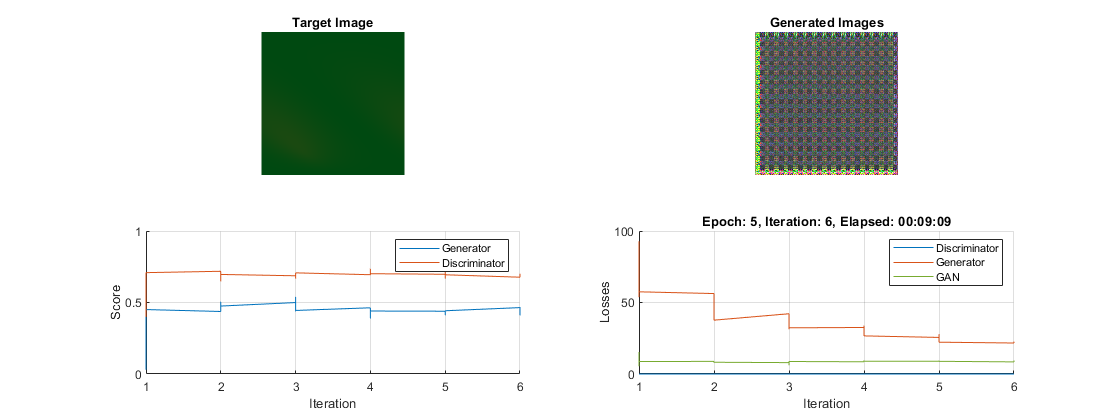

%set starting time
start = tic;

% timestamp = strcat("p2p-", datestr(now, 'yyyymmdd-HHMMSS'));

% Loop over Epochs.
while Epoch <= MaxEpochs
    
    % Reset and shuffle datastore.
    reset(train_dataset);  %sub with train/-dataset
    train_dataset = shuffle(train_dataset);
    
    ms=0;
    while hasdata(train_dataset)
        
        %create minibatch
        while hasdata(train_dataset) && ms<batchSize
            ms=ms+1;
            minids{ms}=read(train_dataset); 
        end
        
        iteration = iteration + 1;
        
        % Loop over mini-batches.
        
        for i=1:ms
            
            % Read mini-batch of data.
            image_file = minids{i};
            
            % Concatenate mini-batch of data and inputs for the
            % Generator network.
            [input_image,real_image]=load_image_train(image_file);
            
            input_image = single(input_image);
            real_image = single(real_image);
            
            % Convert mini-batch of data to dlarray and specify the dimension labels
            % 'SSCB' (spatial, spatial, channel, batch).
            dlinput_image = dlarray(input_image, 'SSCB');
            dlreal_image = dlarray(real_image, 'SSCB');
            
            % If training on a GPU, then convert data to gpuArray.
            if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
                dlinput_image = gpuArray(dlinput_image);
                dlreal_image = gpuArray(dlreal_image);
            end
            
            % Evaluate the model gradients and the generator state using
            % dlfeval and the modelGradients functions
            
            [gradientsGenerator, gradientsDiscriminator, stateGenerator, scoreGenerator, scoreDiscriminator,dLoss,gLoss,LossL1,ganLoss] = ...
                dlfeval(@modelGradients, generator, discriminator, dlreal_image, dlinput_image,learnRate);
            generator.State = stateGenerator;
            
            
            %=====================
            % Update Generator
            
            %[updatedParams, obj.AvgGradient, obj.AvgGradientSq] = adamupdate(params,gradients,obj.AvgGradient,obj.AvgGradientSq,obj.Iteration, obj.LearnRate, obj.Beta1, obj.Beta2);
            [generator.Learnables,trailingAvgGenerator, trailingAvgSqGenerator] = adamupdate(generator.Learnables,gradientsGenerator...
                ,trailingAvgGenerator,...
                trailingAvgSqGenerator,...
                iteration,...
                generator_optimizer.InitialLearnRate,...
                generator_optimizer.GradientDecayFactor,...
                generator_optimizer.SquaredGradientDecayFactor);
            
            %======================
            % Update Discriminator
            
            [discriminator.Learnables, trailingAvgDiscriminator, trailingAvgSqDiscriminator] = adamupdate(discriminator.Learnables,gradientsDiscriminator,...
                trailingAvgDiscriminator,...
                trailingAvgSqDiscriminator,...
                iteration,...
                discriminator_optimizer.InitialLearnRate,...
                discriminator_optimizer.GradientDecayFactor,...
                discriminator_optimizer.SquaredGradientDecayFactor);
            
            
            
            % Every validationFrequency iterations, display batch of generated images using the
            % held-out generator input Validation set
            if mod(iteration,validationFrequency) == 0 || iteration == 1
                % Generate images using the held-out generator input.
                [ValRange,~]=size(val_dataset.Files);
                SelVal=round(rand()*(ValRange-1))+1;
                [inp,target]=load_img(val_dataset.Files{SelVal},'.png',1,2);
                [inp]=normalize_img(inp,1,'forward');
                inp=dlarray(inp,"SSCB");
                Prediction = forward(generator,inp);
                Prediction = tanh(Prediction);
                % Tile and rescale the images in the range [0 1].
                
                
                I = gather(extractdata(Prediction));
                I = (I+1).*0.5;
                
                
                % Display the images.
                subplot(2,2,1);
                imshow(target); % ,globalmap);
                xticklabels([]);
                yticklabels([]);
                title("Target Image");
                
                
                subplot(2,2,2);
                imshow(I);
                xticklabels([]);
                yticklabels([]);
                title("Generated Images");
            end
            
            % Update the scores plot
            subplot(2,2,3)
            addpoints(lineScoreGenerator,iteration,...
                double(gather(extractdata(scoreGenerator))));
            
            addpoints(lineScoreDiscriminator,iteration,...
                double(gather(extractdata(scoreDiscriminator))));
            
            % Update the losses plot
            subplot(2,2,4)
            addpoints(lineDLoss,iteration,...
                double(gather(dLoss)));
            
            addpoints(lineGLoss,iteration,...
                double(gather(gLoss)));
            
            addpoints(lineGanLoss,iteration,...
                double(gather(ganLoss)));
            
            % Update the title with training progress information.
            D = duration(0,0,toc(start),'Format','hh:mm:ss');
            title(...
                "Epoch: " + Epoch + ", " + ...
                "Iteration: " + iteration + ", " + ...
                "Elapsed: " + string(D))
            
            drawnow
        end
        ms=0;
    end
    
    
    %Save training to checkpoint:
    if mod(Epoch,saveFreq)==0
        %Define items to save to checkpoint   - %currently dont save scores or durations
        Modelchkpt = struct('saved_gen',generator,...
            'saved_disc',discriminator,...
            'saved_gen_opt',generator_optimizer,...
            'saved_disc_opt',discriminator_optimizer,...
            "saved_epoch",Epoch,...
            "saved_it",iteration,...
            "saved_AvgGenerator",trailingAvgGenerator,...
            "saved_AvgSqGenerator",trailingAvgSqGenerator,...
            "saved_AvgDiscriminator",trailingAvgDiscriminator,...
            "saved_AvgSqDiscriminator",trailingAvgSqDiscriminator,...
            "saved_scoreGenerator", scoreGenerator,...
            "saved_scoreDiscriminator",scoreDiscriminator,...
            "saved_dLoss",dLoss,...
            "saved_gLoss",gLoss,...
            "saved_LossL1",LossL1,...
            "saved_ganLoss",ganLoss) ;
        checkpointFilename = ['FEANet_checkpoint_' num2str(Epoch) '_' num2str(iteration) '.mat']; %s_%04d.mat', datestr(now, 'YYYY-mm-DDTHH-MM-ss'), epoch);
        Modelchkpt = gather(Modelchkpt);
        save(fullfile(checkpoint_dir, Dataset, checkpointFilename), 'Modelchkpt');
        %update list of checkpoints
        if ~exist(checklistFile,"file")
            checklist{1,1}{:}=checkpointFilename;
            save(fullfile(checklistFile), 'checklist');
        else
            load(checklistFile,"-mat");
            checklist{length(checklist)+1,1}{:}=checkpointFilename;
            save(fullfile(checklistFile), 'checklist');
        end
%         load splat;
%         sound(y,Fs);
        clear checklist...
            Modelchkpt;
    end
    Epoch = Epoch+1;
end

set(f,'WindowStyle','docked') % Insert the figure to dock
figureName = 'Loss & Score for netwrok training.fig';
savefig(f,[ resultsPath '\' figureName])
%close f;
%load handel;
%sound(y,Fs);

# Validate Predictions 

To generate a "Prediction" we simply use the trained portion of the Neural Network Architecture - the Generator.

As before an input image is loaded, normalized -> passed through the generator -> reverse normalized and displayed.

Furthermore we can utilize MATLABs "surf" function to display the Deflections as a surface.

The scaling for the deflections/Stresses is derived from the 1st "red" channel of the initial colormap utilized during dataset generation.

[0-255] corresponding to [0-MaxZ] 

## Pass user input to Generator

[query]=load_img('test.png','.png',1,1);
[query]=normalize_img(query,1,'forward');
query=dlarray(query,"SSCB");
% If training on a GPU, then convert data to gpuArray.
if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
    query = gpuArray(query);
end
Prediction=forward(generator,query);
Prediction=tanh(Prediction);
Prediction=normalize_img(Prediction,1,'backward');
Prediction=gather(extractdata(Prediction));
subplot(1,1,1);
imshow(Prediction)

## Compare Results of all saved Generations

Here we can step through the successive saved Generator Epoch checkpoints to see how the results change (and hopefully improve) with successive training.

checkpointName = '\FEANet*';
checkpointFile=fullfile(checkpoint_dir, Dataset, checkpointName);
files=dir(checkpointFile);
files=natsortfiles({files.name});
%number of saved checkpoints
count=length(files);

%how to choose an input - randomly/specific entry
input=0;

switch input
    case 0
        [ValRange,~]=size(val_dataset.Files);
        SelVal=round(rand()*(ValRange-1))+1;
        [input,target]=load_img(val_dataset.Files{SelVal},'.png',1,2);
    case 1
        [ValRange,~]=size(val_dataset.Files);
        SelVal=575;
        [input,target]=load_img(val_dataset.Files{SelVal},'.png',1,2);
end
 ;

val_dataset.Files{SelVal}
cla;
subplot(1,2,1);
hold on;
imshow(target(:,:,:));
subplot(1,2,2);
imshow(target(:,:,1));
hold off


## Closer inspection of Validation Results

here we are only looking at the first Channel which represents Deflection/Stress values

abs.Error     =     | V - Vapprox |

rel.Error     =     | 1 - (Vapprox / V) |

Relative Percent Difference is then:

RPD         =     |V - Vapprox| / ((V+Vapprox)/2) 

                =    2 x abs.Error / (V+Vapprox)

Pre-allocate space for results:

- Prediction

- abs.Er

- rel.Er

- RPD

Results=zeros([256,256,3,count*4]);

Clear variables if run previously

clear   absEr...
    relEr...
    RPD;
close all
% g=figure;

**Locate max force position for test purposes** (before normalization!)

maxval=0
for i=1:256
    for j=1:256
        if input(i,j,1)>maxval
            maxval=input(i,j,1);
            x=j;
            y=i;
        end
    end
end
if maxval==0  %choose middle pixel if no values
    x=127;
    y=127;
end

Prepare Input image for Generator inputs:

[inp]=normalize_img(input,1,'forward'); %change from "input" to "inp" to avoid corruption is sections rerun
inp=dlarray(inp,"SSCB");
% If training on a GPU, then convert data to gpuArray.
if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
    inp = gpuArray(inp);
end


Run validation input through each saved Generator epoch

j=0;
for index=1:count
    
    checklistName = files{index};
    checklistFile=fullfile(checkpoint_dir, Dataset, checklistName);
    
    [~,~,generator,~,Epoch,iteration,~,~,~,~]=load_checkpoint(checkpoint_dir, Dataset, checklistFile,-1);
    
    %Store checkpoint version
    Epochs(index)=Epoch;
    Iterations(index)=iteration;
    
    %Make Prediction for input
    Prediction = forward(generator,inp);
    Prediction = tanh(Prediction);
    Prediction = normalize_img(Prediction,1,'backward');
    Prediction = gather(extractdata(Prediction));
    
    %Save Prediction to "Results Array"
    Results(:,:,index,1)=[Prediction(:,:,1)];
    
    %Calculate errors:
    %===================
    %Absolute Error
    dif(:,:,1)=(target(:,:,1)+1)-(Prediction(:,:,1)+1);
    absEr=abs(dif);
    %Relative Error
    relEr(:,:,1)=abs(1- dif(:,:,1)./target(:,:,1));
    %Relative Percent Difference (RPD)
    RPD=abs(Prediction(:,:,1)-(target(:,:,1)))./((Prediction(:,:,1))+(target(:,:,1))/2);
    
    
    %Save Errors to "Results Array"
    Results(:,:,index,2)=[absEr];
    Results(:,:,index,3)=[relEr];
    Results(:,:,index,4)=[RPD];
    
    j=j+1;
    
end

Plot the results

Tile=Results(:,:,:,1);
out=imtile(Tile);
f = figure;
subplot(1,1,1);
Tile=imshow(out);
imwrite(out,[Dataset '_validation_' num2str(SelVal) '_.png']);
set(f,'WindowStyle','docked') % Insert the figure to dock
figureName = 'Training Progression.fig';
savefig(f,[ resultsPath '\' figureName])
clear Tile out;

## extract values at test positions:

for i=1:count
    targetVal(i)=target(y,x,1);
    targetMean(i)=mean(target(:,:,1),"all");
    
    PredVal(i)=Results(y,x,i,1);
    PredMean(i)=mean(Results(:,:,i,1),"all");
    
    erVal(i)=(Results(y,x,i,2));
    erMean(i)=mean(Results(:,:,i,2),"all");
    
    %     erRel(i)=(Results(y,x,i,3));
    %     erRelMean(i)=mean(Results(:,:,i,3),"all");
    %     These two are omitted as Relative errors have infinite/undefined
    %     values
    
    erRPD(i)=(Results(y,x,i,4));
    erRPDmean(i)=mean(Results(:,:,i,4),"all");
    
end


F=figure;
subplot(1,3,1);
hold on
plot(Epochs,targetVal)  ;
plot(Epochs,PredVal);
plot(Epochs,erVal);
legend('Target-Max.value','Predicted-Max.value','DAE-Max.value');
hold off
subplot(1,3,2);
hold on
plot(Epochs,targetMean);
plot(Epochs,PredMean);
plot(Epochs,erMean);
legend('Target-Mean','Predicted-Mean','DAE-Mean');
hold off
subplot(1,3,3);
hold on

% plot(Epochs,erRel);
% plot(Epochs,erRelMean);
plot(Epochs,erRPD);
plot(Epochs,erRPDmean);

legend('RPD-Max.value','RPD-Mean');
hold off
set(F,'WindowStyle','docked') % Insert the figure to dock
figureName = 'Max-Mean-RPD-Max Target Predicted DAE.fig';
savefig(F,[ resultsPath '\' figureName])
clear F;


g=figure;
subplot(1,1,1);
frame=zeros(256*count,256*5);
for i=0:count-1
    %Target
    frame(i*256+1:(i+1)*256,1:256) = target(:,:,1);
    %Prediction
    frame(i*256+1:(i+1)*256,257:512) = Results(:,:,i+1,1);
    %abs.Error
    frame(i*256+1:(i+1)*256,513:768) = Results(:,:,i+1,2);
    %rel.Error
    frame(i*256+1:(i+1)*256,769:1024) = Results(:,:,i+1,3);
    %R.P.D.
    frame(i*256+1:(i+1)*256,1025:1280) = Results(:,:,i+1,4);
    
end
out = imshow(frame);

set(g,'WindowStyle','docked') % Insert the figure to dock
figureName = 'Image with all error.fig';
savefig(g,[ resultsPath '\' figureName])


% PredResults = subplot(1,1,1);
% lineTarget = animatedline(PredResults,'Color',[0 0.447 0.741]);
% linePrediction = animatedline(PredResults, 'Color', [0.85 0.325 0.098]);
% legend('Target','Prediction');
% % ylim([0 1]);
% xlabel("Epoch");
% ylabel("Max");
% grid on;


% %Calculate errors
% %Absolute Error
% dif(:,:,1)=(target(:,:,1)+1)-(Prediction(:,:,1)+1);
% absEr=abs(dif);
% %Relative Error
% relEr(10:246,10:246,1)=abs(1- dif(10:246,10:246,1)./target(10:246,10:246,1));
%
% %Relative Percent Difference
% RPD=abs(Prediction(10:246,10:246,1)-(target(10:246,10:246,1))./(abs(Prediction(10:246,10:246,1))+abs(target(10:246,10:246,1))));

% ax1=subplot(2,4,1);
% imshow(Prediction(:,:,1));
% title('Prediction');
%
% ax2=subplot(2,4,2);
% imshow(target(:,:,1));
% title('Target');
%
% ax3=subplot(2,4,3);
% imshow(absEr);
% title('Abs. Error');
%
% ax4=subplot(2,4,4);
% imshow(relEr);
% title('Relative Error');
%
% ax5=subplot(2,4,5);
% pred_surf=surf(Prediction(:,:,1));
% % shading interp
% title('Prediction');
%
% ax6=subplot(2,4,6);
% tar_surf=surf(target(:,:,1));
% % shading interp
% title('Target');
%
% ax7=subplot(2,4,7);
% dif_surf=surf(absEr);
% % shading interp
% title('Abs. Error');
%
% ax8=subplot(2,4,8);
% rel_surf=surf(RPD);%relEr);
% % shading interp
% title('Relative Error');
%
% Max=max(Prediction(10:246,10:246,1),[],'all');
% if max(target(10:246,10:246,1),[],'all')>Max
%     Max=max(target(10:246,10:246,1),[],'all');
% end
%
% Link = linkprop([ax5, ax6, ax7],{'CameraUpVector', 'CameraPosition', 'CameraTarget','Projection','XLim', 'YLim', 'ZLim','CLim'});
% Link2 = linkprop([tar_surf, pred_surf, dif_surf,rel_surf],{'EdgeColor'});
% ax5.Projection='perspective';
% ax5.ZLim=[0 Max];
% ax5.CLimMode='manual';
% ax5.CLim=[0 Max];
% ax1.CLimMode='manual';
% ax1.CLim=[0,Max];
% ax2.CLimMode='manual';
% ax2.CLim=[0,Max];
% ax3.CLimMode='manual';
% ax3.CLim=[0,Max];
%
% set([tar_surf],'EdgeColor','none');
% caxis manual;
% ax8.ZLim=[0,2];
% ax8.CLim=[0,1];
% ax8.Colormap=jet;

% setappdata(gcf, 'StoreTheLink', Link);
% setappdata(gcf, 'StoreTheLink', Link2);
 

Write output to animate Gif file

filename = [Dataset '_Validation_' num2str(SelVal) '.gif']; % Specify the output file name
i=0;
cropped=zeros(256,256*5);
for index = 1:count-1
    cropped(:,:)=frame(1+i*256:256+i*256,1:1280);
    cropped=(cropped.*255);
    %     warning('off', MSGID)
    if index == 1
        imwrite(cropped,jet(256),filename,'gif','LoopCount',Inf,'DelayTime',1);
        w = warning('query','last'); %disable "out of range" warnings.
        wid=w.identifier;
        warning('off',wid);
    else
        imwrite(cropped,jet(256),filename,'gif','WriteMode','append','DelayTime',1);
    end
    i=i+1;
end

[gifImage cmap] = imread(filename, 'Frames', 'all');
implay(gifImage); %only displays grayscale in MATLAB - open seperately to view in color

## Statistical Validation

Here we will run a similar validation across the entire set of entries in the Validation subset of the Datasets.

%count number of files in Validation set:
ValCount=size(val_dataset.Files,1);

%Reduce for now to check if all works:
%^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^
% ValCount=round(ValCount/4);

%Count the number of Saved Epochs:
checkpointName = '\FEANet*';
checkpointFile=fullfile(checkpoint_dir, Dataset, checkpointName);
files=dir(checkpointFile);
files=natsortfiles({files.name});

CheckCount=length(files);

%We want to store:
%Errors:
%DAE - Target
%DAE - Mean
%RPD - Target
%RPD - Mean
%For each Validation entry
%For each Epoch

%Pre Allocate a Matrix to Store the above:
%Rows = Validation entry [1; ; ; ; ;ValCount]
%Colums = Errors [DAETarget, DAEMean, RPDTarget, RPDMean]
%Depth = Model Epochs [1st.....Nth Epoch]
Results=zeros(ValCount,4,CheckCount);
Epochs=zeros(CheckCount,1);
%Sequence:
%Load ith Checkpoint
%   Load Jth Validation entry
%       Make Prediction
%       Calculate errors
%       Store Errors
%   Increment Validation entry
%Increment Epoch

for i=1:CheckCount
    checklistName = files{i};
    checklistFile=fullfile(checkpoint_dir, Dataset, checklistName);
    
    [~,~,generator,~,Epoch,~,~,~,~,~]=load_checkpoint(checkpoint_dir, Dataset, checklistFile,-1);
    
    %Store checkpoint version Epoch
    Epochs(i)=Epoch;
    
    for j=1:ValCount
        [inp,target]=load_img(val_dataset.Files{j},'.png',1,2);
        
        %Locate max force position for test purposes (before normalization!)
        maxval=0;
        for k=1:256
            for l=1:256
                if inp(k,l,1)>maxval
                    maxval=inp(k,l,1);
                    x=l;
                    y=k;
                end
            end
        end
        if maxval==0  %choose middle pixel if no values
            x=127;
            y=127;
        end
        
        %Prepare Input image for Generator inputs:
        [inp]=normalize_img(inp,1,'forward');
        inp=dlarray(inp,"SSCB");
        if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
            inp = gpuArray(inp);
        end
        
        %Make Prediction using Generator
        Prediction = forward(generator,inp);
        Prediction = tanh(Prediction);
        Prediction = normalize_img(Prediction,1,'backward');
        Prediction = gather(extractdata(Prediction));
        
        %Calculate errors:
        %===================
        %Absolute Error
        dif=target(:,:,1)-Prediction(:,:,1);
        Results(j,1,i)=abs(dif(y,x,1));
        Results(j,2,i)=mean(abs(dif),"all");
        
        %Relative Percent Difference (RPD)
        RPD=abs(Prediction(:,:,1)-(target(:,:,1)))./((Prediction(:,:,1))+(target(:,:,1))/2);
        Results(j,3,i)=RPD(y,x,1);
        Results(j,4,i)=mean(RPD(:,:,1),"all");
        
    end
end


### Plot end results

Plots best viewed as external figures!



%DAE-Target
for i=1:ValCount
    extract1(i,:)=Results(i,1,:,1);
end


%displayed first to last from back (latest Epoch in front)
f = figure;
waterfall(flipud(transpose(extract1)))
view([28 35])
title('DAE values at Target location for all samples in Validation set across all Epochs')
set(f,'WindowStyle','docked') % Insert the figure to dock
figureName = 'DAE values at Target location for all samples in Validation set across all Epochs.fig';
savefig(f,[ resultsPath '\' figureName])
clear f



RidgeLine(-0.01,0.1,2000,Epochs,extract1,'ksdensity','Kernel smoothed Density plots for DEA-Target values across all Validation samples and Epochs',resultsPath)
% set(gcf,'WindowStyle','docked') % Insert the figure to dock
% figureName = 'Kernel smoothed Density plots for DEA-Target values across all Validation samples and Epochs.fig';
% savefig(f,[ resultsPath '\' figureName])


RidgeLine(-0.01,0.5,2000,Epochs,extract1,'normal','Waterfall plot of DEA-Target Normal Distributions across all Epochs',resultsPath)


%DAE-Mean

for i=1:ValCount
    extract2(i,:)=Results(i,2,:);
end
f = figure;
waterfall(flipud(transpose(extract2)))
view([28 35])
set(f,'WindowStyle','docked') % Insert the figure to dock
figureName = 'DAE-Mean samples in Validation set across all Epochs.fig';
savefig(f,[ resultsPath '\' figureName])

% RidgeLine(-0.01,0.05,1000,Epochs,extract2,'waterfall','Waterfall plot of DAE at Target point')
RidgeLine(-0.001,0.05,1000,Epochs,extract2,'ksdensity','Kernel smoothed Density plots for DEA-Mean values across all Validation samples and Epochs',resultsPath)


RidgeLine(-0.01,0.05,1000,Epochs,extract2,'normal','Waterfall plot of DAE-Mean Normal Distributions across all Epochs',resultsPath)

%RPD-Target
% subplot(2,2,3);

for i=1:ValCount
    extract3(i,:)=Results(i,3,:);

end
f = figure
waterfall(flipud(transpose(extract3)))
set(f,'WindowStyle','docked') % Insert the figure to dock
figureName = 'RPD-Target samples in Validation set across all Epochs.fig';
savefig(f,[ resultsPath '\' figureName])
close all
RidgeLine(-0.2,2,1000,Epochs,extract3,'ksdensity','Kernel smoothed Density plots for RPD-Target values across all Validation samples and Epochs',resultsPath)
RidgeLine(-0.2,2,1000,Epochs,extract3,'normal','Waterfall plot of RPD-Target Normal Distributions across all Epochs',resultsPath)


%RPD-Mean

for i=1:ValCount
    extract4(i,:)=Results(i,4,:);
end
f= figure
waterfall(flipud(transpose(extract4)))
set(f,'WindowStyle','docked') % Insert the figure to dock
figureName = 'RPD-Mean samples in Validation set across all Epochs.fig';
savefig(f,[ resultsPath '\' figureName])

RidgeLine(-0.2,2,1000,Epochs,extract4,'ksdensity','KS Density Waterfall plot of RPD-Mean of Val. dataset across all Epochs',resultsPath)
RidgeLine(-0.2,2,1000,Epochs,extract4,'normal','Waterfall plot of Validation set RPD-Mean Normal Distributions across all Epochs',resultsPath)




% Save work space into results
filename = 'WS.mat';
save([ resultsPath '\' Dataset '_' filename])